# 2. Identification water level sensor slope $dh/dr$, $r = R_{sense}/R_{ref}$

## Procedure

The water level sensor is made of 2 resistors: a reference resistor and a resistor sensible to water level. The sensor is connected in a simple voltage divider configuration, which outputs the voltage across the reference resistor $V_{ref}$. Thus, $V_{ref}/V_{cc} = R_{ref}/(R_{ref}+R_{sense})$. The ratio $r = R_{sense}/R_{ref}$ is known to be proportional to water level, i.e., 

$h = (dh/dr) r+h_0$.

**WARNING**: $h_0$ and $h$ are measured relatively to the valve outlet hole, not the bottom of the tank or the zero of the sensor ruler.

 For the identification of the slope of the water level sensor, i.e., $dh/dr$, with $r = R_{sense}/R_{ref}$,the following procedure is proposed:

1 . Open '**identification_sl.slx**';

For each tank:

3. Block the outlet of tank. (Either close the valve; block the oulet with a finger, or (for the upper tanks) clamp the tubes at the outlet of the valve). Note that, depending on the quality of the 3D print, the valves may have a small leaks, so the second and third methods are recomended;

4.  Add some water to the tank with the pumps by using the sliders of the simulink model;

5. Measure $r$ in the simulink scope and the water level in the sensor ruler $h^*$;

4. Repeat 4. and 5., increasing the water level and measuring the pairs $(r,h^*)$, until enough samples are taken;

5. Since $dh^*/dh = 1$ one can compute $dh/dr$ peforming a linear regression of the samples taken.

## Initialization

clear;

## Tank 1

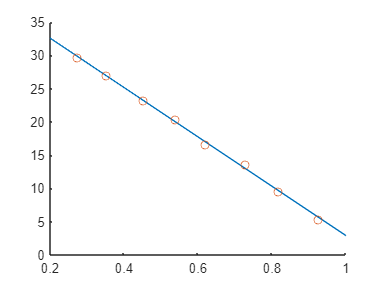

% Height whose reference is the sensor inscription
h = [5.4;9.5;13.6;16.6;20.3;23.2;27.0;29.6];
% r = R_sense/R_ref
r = [0.9269;0.8182;0.7279;0.6203;0.5404;0.4518;0.3522;0.2749];
% Remove outliers
r_out = r(:);
h_out = h(:);
% Perform linear regression
reg = [ones(size(r_out,1),1) r_out]\h_out; 
% Plot linear regression and dataset
figure;
hold on;
plot(0.2:0.1:1,(0.2:0.1:1)*reg(2)+reg(1));
scatter(r,h);
hold off;

% Slope h (cm) vs ratio r = R_sense/R_ref
dh_dr1 = reg(2) % (cm)

dh_dr1 = -37.0922

## Tank 2

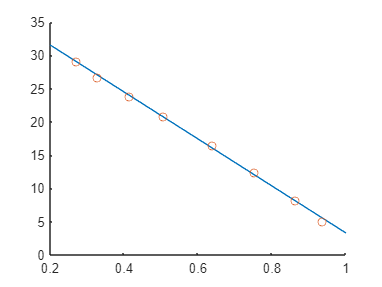

% Height whose reference is the sensor inscription
h = [5.0;8.2;12.4;16.5;20.8;23.8;26.7;29.1];
% r = R_sense/R_ref
r = [0.9365;0.8636;0.7525;0.6381;0.5080;0.4156;0.3283;0.2710];
% Remove outliers
r_out = r(:);
h_out = h(:);
% Perform linear regression
reg = [ones(size(r_out,1),1) r_out]\h_out; 
% Plot linear regression and dataset
figure;
hold on;
plot(0.2:0.1:1,(0.2:0.1:1)*reg(2)+reg(1));
scatter(r,h);
hold off;

% Slope h (cm) vs ratio r = R_sense/R_ref
dh_dr2 = reg(2) % (cm)

dh_dr2 = -35.3299

## Tank 3

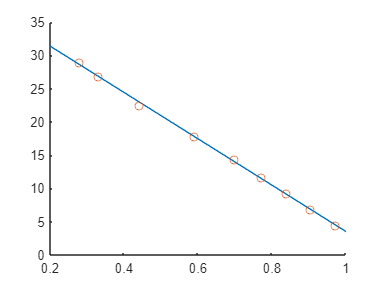

% Height whose reference is the sensor inscription
h = [4.4;6.8;9.2;11.6;14.4;17.8;22.4;26.8;28.9];
% r = R_sense/R_ref
r = [0.9706;0.9030;0.8385;0.7720;0.6987;0.5894;0.4423;0.3300;0.2798];
% Remove outliers
r_out = r(:);
h_out = h(:);
% Perform linear regression
reg = [ones(size(r_out,1),1) r_out]\h_out; 
% Plot linear regression and dataset
figure;
hold on;
plot(0.2:0.1:1,(0.2:0.1:1)*reg(2)+reg(1));
scatter(r,h);
hold off;

% Slope h (cm) vs ratio r = R_sense/R_ref
dh_dr3 = reg(2) % (cm)

dh_dr3 = -34.8339

## Tank 4

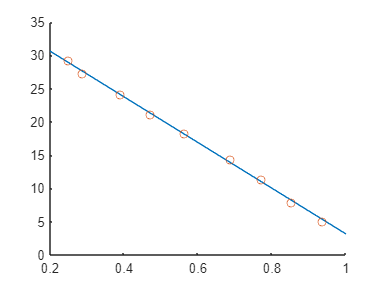

% Height whose reference is the sensor inscription
h = [5.1;7.9;11.4;14.4;18.2;21.1;24.1;27.2;29.2];
% r = R_sense/R_ref
r = [0.9355;0.8518;0.7725;0.6869;0.5636;0.4715;0.3896;0.2880;0.2493];
% Remove outliers
r_out = r(:);
h_out = h(:);
% Perform linear regression
reg = [ones(size(r_out,1),1) r_out]\h_out; 
% Plot linear regression and dataset
figure;
hold on;
plot(0.2:0.1:1,(0.2:0.1:1)*reg(2)+reg(1));
scatter(r,h);
hold off;

% Slope h (cm) vs ratio r = R_sense/R_ref
dh_dr4 = reg(2) % (cm)

dh_dr4 = -34.3379

## Save data

dh_dr = [dh_dr1; dh_dr2; dh_dr3; dh_dr4];
save('./data/dh_dr.mat','dh_dr');
